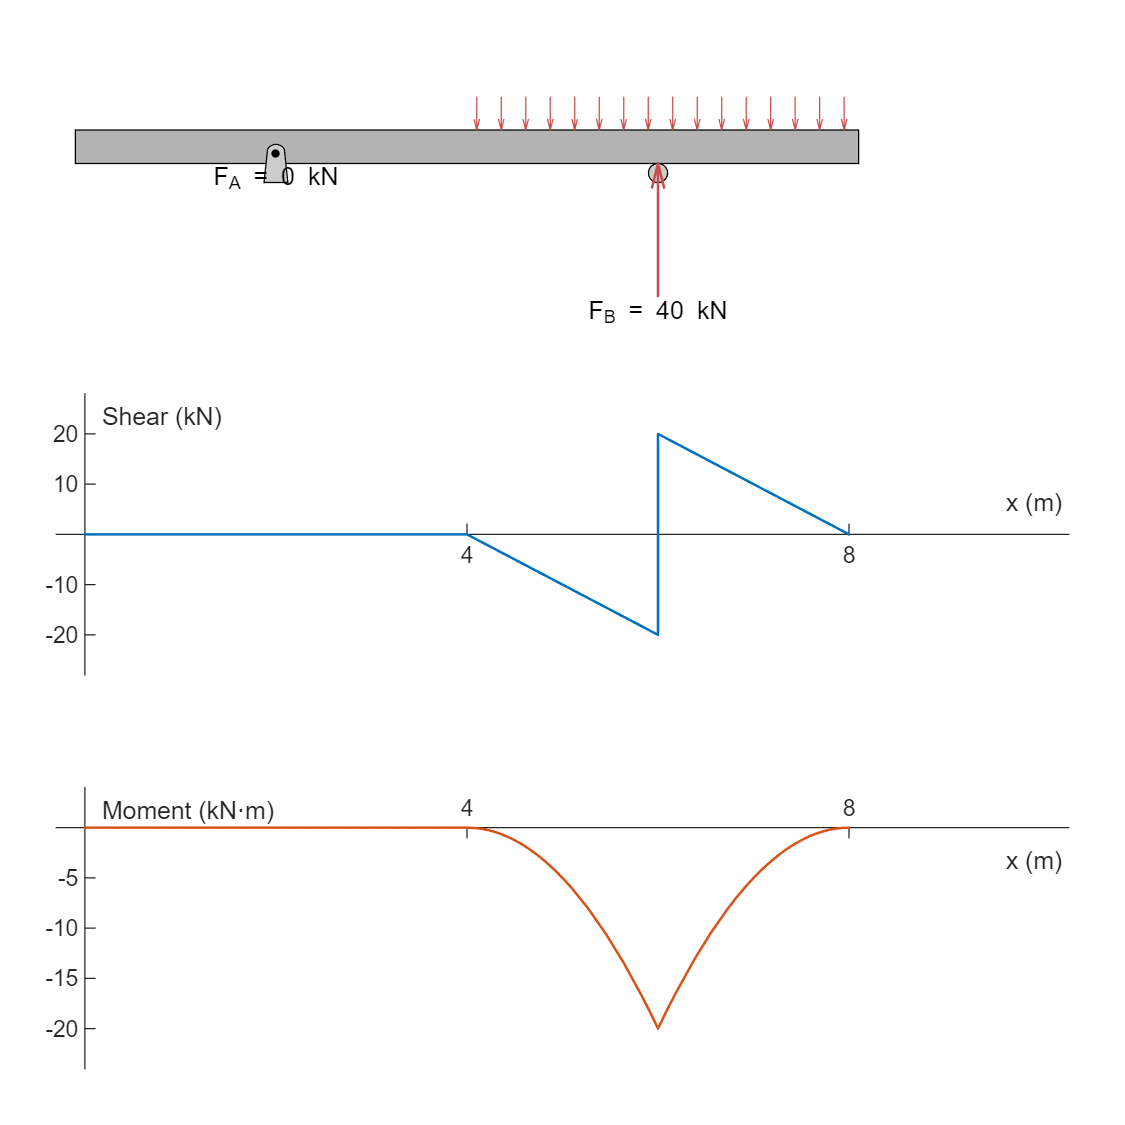

close all
clear

syms x
length = 8; % m
rollerPos = 6; % m (must be <= length)
pinPos = 2; % m (cannot equal the roller position)
Fapplied = -10*heaviside(x-4); % Applied force density (kN/m) as a function of x

shearMomentDiagram(length,Fapplied,rollerPos,pinPos); 

function shearMomentDiagram(length,Fapplied,rollerPos,pinPos)

    if(rollerPos > length)
        rollerPos = length;
        disp("The roller position must be less than the length." + ...
            newline + "It has been automatically set to the length.")
    end
    if(pinPos == rollerPos)
        error("Pin position cannot equal the roller position. Please adjust the positions.")
    end
    
    % Symbolic calculations
    syms x F_A F_B
    Feq = int(sym(Fapplied),0,length) + F_A + F_B == 0;
    Meq = F_A*pinPos + F_B*rollerPos + int(Fapplied*x,0,length) == 0;
    sol = solve([Feq,Meq],[F_A,F_B]);
    FA = double(sol.F_A);
    FB = double(sol.F_B);
    % Symbolic shear and moment 
    shearForce = FA*heaviside(x-pinPos) + FB*heaviside(x-rollerPos) + int(Fapplied,0,x);
    moment = int(shearForce,0,x);

    % Build the figure
    figure("Position",[0 0 600 600])

    % Bar diagram
    subplot("Position",[0.05,0.7,0.9,0.25])
    xLims = barDiagram(length,FA,FB,Fapplied,rollerPos,pinPos);

    % Shear diagram
    subplot("Position",[0.05,0.4,0.9,0.25])
    shearDiagram(length,xLims,shearForce)

    % Moment diagram
    subplot("Position",[0.05,0.05,0.9,0.25])
    momentDiagram(length,xLims,moment)

end

function xLims = barDiagram(length,FA,FB,FappliedSym,rollerPos,pinPos)
    
    % Force arrow calculations
    maxLength = 10;
    xApplied = linspace(0,maxLength,40);
    Fapplied = double(subs(FappliedSym,xApplied));

    % Settings
    barColor = [0.7 0.7 0.7];
    supportColor = [0.8 0.8 0.8];
    reactionColor = [0.8 0.3 0.3];
    appliedColor = [0.8 0.3 0.3];
    barHeight = 0.35;
    offsetx = 0.1;
    rCirc = 0.1;
    pinHeight = 0.1;
    quiverLW = 1;
    labelPosY = rCirc*4;
    circCenter = [rollerPos,-rCirc]; % (xc,yc)
    pinCenter = [pinPos,pinHeight];
    diagramAxisLims = [-rCirc*3,maxLength+rCirc*3,-barHeight,barHeight*2];
    xLims = diagramAxisLims(1:2);
    
    % Bar
    barx = [-offsetx, length+offsetx, length+offsetx, -offsetx];
    bary = [0 0 barHeight barHeight];
    patch(barx,bary,barColor)
    hold on

    % Pin support
    theta = linspace(pi-0.5,0+0.5,50);
    xSupport = rCirc*cos(theta) + pinCenter(1);
    ySupport = rCirc*sin(theta) + pinCenter(2);
    xSupport = [pinPos-offsetx*1.25, xSupport,pinPos+rCirc*2-offsetx*0.75];
    ySupport = [-2*rCirc, ySupport, -2*rCirc];
    patch(xSupport,ySupport,supportColor)
    plot(pinCenter(1),pinCenter(2),"k.","MarkerSize",10)

    % Circle (roller support)
    theta = linspace(0,2*pi,50);
    xcirc = rCirc*cos(theta) + circCenter(1);
    ycirc = rCirc*sin(theta) + circCenter(2);
    patch(xcirc,ycirc,supportColor);    

%     % Length label
%     xvals = [0 length];
%     plot(xvals,[1 1]*labelPosY,"k-|","LineWidth",1)
%     text(mean(xvals),labelPosY,num2str(length) + " m",...
%         "HorizontalAlignment","center","VerticalAlignment","top")
    
    % Force scaling
    Fscale = 4*barHeight/max(abs([FA,FB,Fapplied]));

    % Applied force arrow(s)
    vApplied = Fapplied*Fscale;
    yApplied = xApplied*0+barHeight-(vApplied<0).*vApplied;
    xApplied(xApplied > length) = NaN;
    xText = mean(xApplied.*abs(vApplied))./mean(abs(vApplied));
    quiver(xApplied,yApplied,xApplied*0,vApplied,"Color",appliedColor,"Autoscale","off")

    % Reaction force arrows
    xr = [pinPos, rollerPos];
    vr = [FA*Fscale, FB*Fscale];
    yr = -vr + vr.*(vr < 0);
    quiver(xr,yr,xr*0,vr,"Color",reactionColor,"AutoScale","off",...
            "LineWidth",quiverLW)
    yrText = -abs(vr);
    text(xr,yrText,["F_A = " + num2str(FA,3) + " kN","F_B = " + num2str(FB,3) + " kN"],...
        "HorizontalAlignment","center","VerticalAlignment","top")

    axis(diagramAxisLims)
    axis equal
    axis off

    ax = gca;
    ax.Clipping = "off";

    yAxLims = get(gca,"ylim");
    text(xText,yAxLims(2),"F(x) = " + string(FappliedSym) +" [kN/m]",...
        "HorizontalAlignment","center","VerticalAlignment","baseline")

end

function shearDiagram(length,xLims,shearForce)

    % Settings
    shearLW = 1;

    % Plot
    fp = fplot(shearForce,[0-1e-2,length+1e-2],"LineWidth",shearLW);
    yLims = minmax(fp.YData);
    
    xlabel("x (m)")
    ylabel("Shear (kN)")
    xlim(xLims)
    if(~all(yLims == 0))
        ylim([yLims(1)-diff(yLims)*0.2,yLims(2)+diff(yLims)*0.2])
    end
    xticks([0,length/2,length])
    box off
    ax = gca;
    ax.XAxisLocation = "Origin";
    ax.YAxisLocation = "Origin";
    ax.Clipping = "off";
end

function momentDiagram(length,xLims,moment)

    % Settings
    lw = 1;
    color = [0.8500    0.3250    0.0980];

    % Plot
    fp = fplot(moment,[0-1e-2,length+1e-2],"LineWidth",lw,"Color",color);
    yLims = minmax(fp.YData);
    
    xlabel("x (m)")
    ylabel("Moment (kN·m)")
    xlim(xLims)
    if(~all(yLims == 0))
        ylim([yLims(1)-diff(yLims)*0.2,yLims(2)+diff(yLims)*0.2])
    end
    xticks([0,length/2,length])
    box off
    ax = gca;
    ax.XAxisLocation = "Origin";
    ax.YAxisLocation = "Origin";
    ax.Clipping = "off";
    
end